path = 'D:\Desktop\Studie\Diploma\Audio data\wav\60 нот.wav'

path = 'D:\Desktop\Studie\Diploma\Audio data\wav\60 нот.wav'

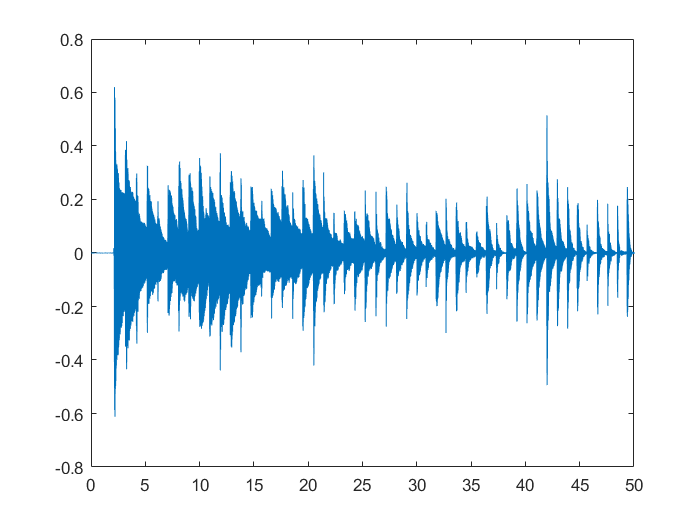

[y, Fs] = audioread(path);


Tsmall = 50;
ts = 0:1/Fs:Tsmall-1/Fs;
z = y(1:Tsmall*Fs,1);

imp = [1 0 0 0.5 0 0 0.25];

A = conv(z, imp);

sound(A(20*Fs:24*Fs), Fs)
sound(z(20*Fs:24*Fs), Fs)

% W = cwt(z, 'bump', Fs);
Tend = length(y) / Fs;
t = 0:1/Fs:Tend-1/Fs;


figure (1)
plot(ts, z)


figure (2)
cwt(z, 'bump', Fs); %???

path = 'D:\Desktop\Studie\Diploma\Audio data\wav\60 нот.wav'

path = 'D:\Desktop\Studie\Diploma\Audio data\wav\60 нот.wav'

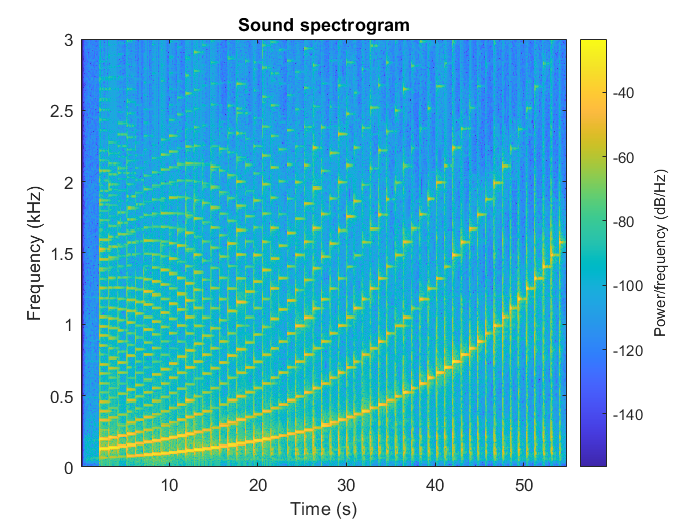

[y, Fs] = audioread(path);

Tsmall = 55;
ts = 0:1/Fs:Tsmall-1/Fs;
z = y(1:Tsmall*Fs,1);

spectrogram(z,6000, 2000,6000,Fs,'yaxis')
title('Sound spectrogram')
ylim([0 3])

path = 'D:\Desktop\Studie\Diploma\Audio data\wav\Отрывок композиции для анализа-1.wav'